clearvars
F = readtable("Flightlogs.csv")

F = 18539×6 table
    timestamp_ms_    VFR_HUD_groundspeed    ATTITUDE_roll    ATTITUDE_pitch    ATTITUDE_rollspeed    ATTITUDE_pitchspeed
    _____________    ___________________    _____________    ______________    __________________    ___________________

       93.914             0.0041319           0.024433         -0.066774          -7.7659e-05             0.00039723    
       193.91             0.0041319           0.024433         -0.066774          -7.7659e-05             0.00039723    
       293.91             0.0038856             0.0245         -0.066808          -0.00031902             0.00094264    
       393.91             0.0038856             0.0245         -0.066808          -0.00031902             0.00094264    
       493.91             0.0038856             0.0

F2 = csvread("Flightlogs.csv",1);
i = 1;
j = 1;
size = length(F2);
Timestamp = 1:size;
Groundspeed = F2(1:end,2);
Roll= F2(1:end,3);
Pitch = F2(1:end,4);
Rollspeed = F2(1:end,5);
Pitchspeed = F2(1:end,6);

SRoll = zeros(size,1);
SPitch =zeros(size,1) ;
RollMax = zeros(size,1);
PitchMax =zeros(size,1) ;
SRollspeed =zeros(size,1) ;
SPitchspeed =zeros(size,1) ;

for n=1:size
    if Groundspeed(n)<= 0.07
        SRoll(i) = Roll(n);
        SPitch(i) = Pitch(n);
        SRollspeed(i) = Rollspeed(n);
        SPitchspeed(i) = Pitchspeed(n);
       % nval(i) = n; 
        i=i+1;
    end
end
RollMax = max(abs(F2(1:end,3)))

RollMax = 0.1471

PitchMax = max(abs(F2(1:end,4)))

PitchMax = 0.1104

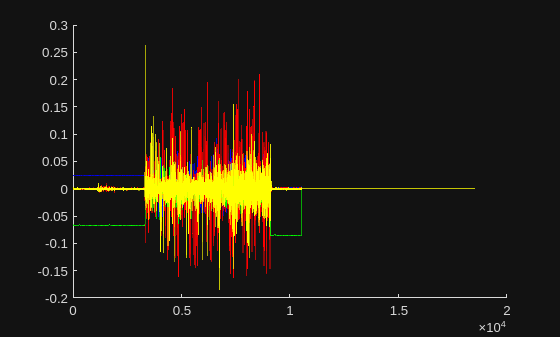

i=1;
hold on
plot(1:length(SRoll),SRoll,'b')
plot(1:length(SRoll),SRollspeed,'r')
plot(1:length(SRoll),SPitch,'g')
plot(1:length(SRoll),SPitchspeed,'y')
hold off

MSRoll = max(abs(SRoll))

MSRoll = 0.1077

%MSRollNval; 
MSRollspeed = max(abs(SRollspeed))

MSRollspeed = 0.2085

%MSRollspeedNval;
MSPitch = max(abs(SPitch))

MSPitch = 0.0861

%MSPitchNval;
MSPitchspeed= max(abs(SPitchspeed))

MSPitchspeed = 0.2629

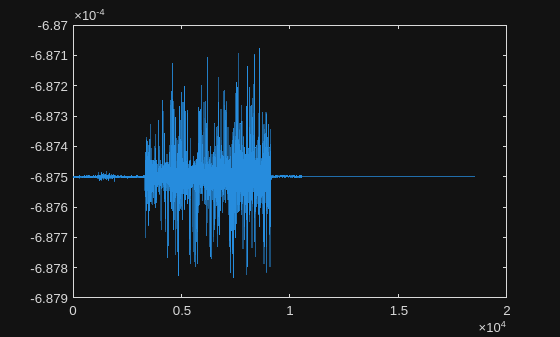

%MSPitchspeedNval;
[p,S,mu] = polyfit(1:length(SPitch),SRollspeed,7);
plot(polyval(p,SRollspeed,S,mu))


RollAcc = zeros(size,1);
PitchAcc = zeros(size,1);

for n=1:size-1
    if abs(SRollspeed(n+1)-SRollspeed(n))/0.1 > 0
        RollAcc(i) = abs(SRollspeed(n+1)-SRollspeed(n))/0.1;
        i=i+1;
    end

    if abs(Pitchspeed(n+1)-Pitchspeed(n))/0.1 > 0
        PitchAcc(j) = abs(SPitchspeed(n+1)-SPitchspeed(n))/0.1;
        j=j+1;
    end
end
RollAccMax = max(RollAcc)

RollAccMax = 3.2372

PitchAccMax = max(PitchAcc)

PitchAccMax = 3.0224